Zad1

G0 =
 
     3.1623e+05
  ----------------
  (s+10) (s+100)^2
 
Continuous-time zero/pole/gain model.



% G0=zpk([],[],sqrt(10))
kp=3.88;
k=58.61;
k1=0.13;
feedback(G0,1)

ans =
 
            3.1623e+05
  -------------------------------
  (s+147.9) (s^2 + 62.11s + 2814)
 
Continuous-time zero/pole/gain model.



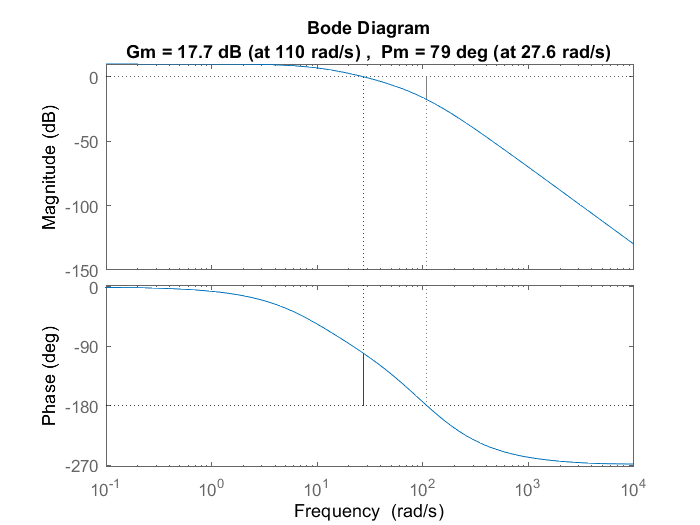

margin(G0)

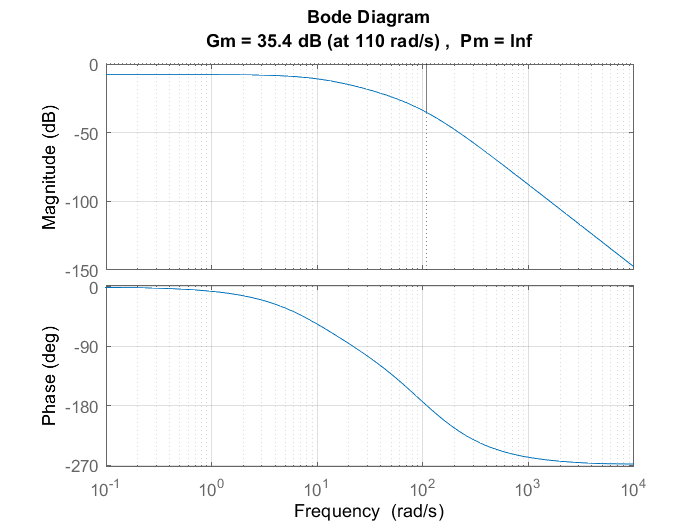

margin(k1*G0)
grid on


sys=tf(sqrt(10), conv([0.1 1], conv([0.01 1],[0.01 1])));sys=zpk(sys)

sys =
 
     3.1623e+05
  ----------------
  (s+100)^2 (s+10)
 
Continuous-time zero/pole/gain model.



Zad2

G0=zpk([-1],[-sqrt(10) -10 -10 0],1000)

G0 =
 
       1000 (s+1)
  --------------------
  s (s+3.162) (s+10)^2
 
Continuous-time zero/pole/gain model.



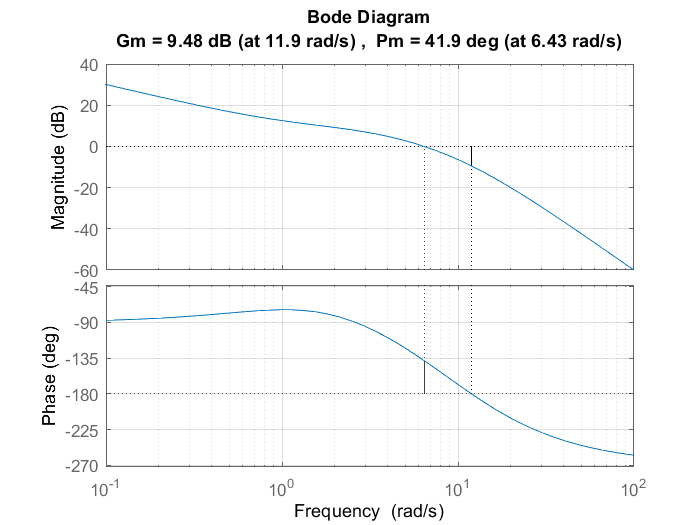

margin(G0);
grid on;

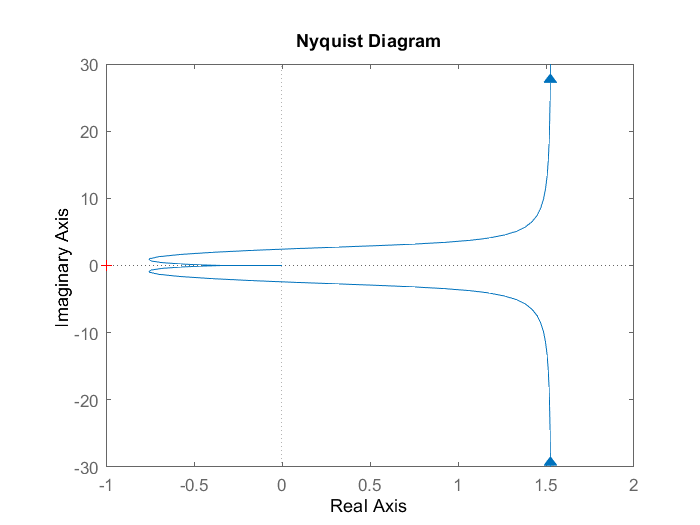


figure
P=nyquistplot(G0);

% xlim([-200,100])
% ylim([-100 1000])
setoptions(P,'ShowFullContour','on')

syms w G0(s) real

%s=tf('s');
G0(s)=sqrt(10)*(s+1)/s/(s/sqrt(10)+1)/(s/10+1)^2;
absolute=abs(G0(1i*w))

$$absolute = \frac{\sqrt{10}\,\sqrt{w^{2}+1}}{\left|w\right|\,\sqrt{\frac{w^{2}}{10}+1}\,\left(\frac{w^{2}}{100}+1\right)}$$

phase=angle(G0(1i*w))

$$phase = \text{angle}\left(-\frac{\left(1+w\,\mathrm{i}\right)\,\mathrm{i}}{w\,{\left(1+\frac{w\,\mathrm{i}}{10}\right)}^{2}\,\left(1+\frac{\sqrt{10}\,w\,\mathrm{i}}{10}\right)}\right)$$


P=simplify(real(G0(1i*w)))

$$P = -\frac{1000\,\sqrt{10}\,w^{2}-80000\,\sqrt{10}+19000\,w^{2}+100000}{\left(w^{2}+10\right)\,{\left(w^{2}+100\right)}^{2}}$$

[num, den]=numden(simplify(real(G0(1i*w))));
n=sym2poly(num);
d=sym2poly(den);
P=zpk(tf(n,d))

P =
 
  -22162 (s-2.627) (s+2.627)
  --------------------------
   (s^2 + 10) (s^2 + 100)^2
 
Continuous-time zero/pole/gain model.



valP=evalfr(P,0)

valP = 1.5298


Q=simplify(imag(G0(1i*w)))

$$Q = -\frac{100000\,\sqrt{10}+19000\,\sqrt{10}\,w^{2}+80000\,w^{2}-1000\,w^{4}}{w\,\left(w^{2}+10\right)\,{\left(w^{2}+100\right)}^{2}}$$

[num, den]=numden(simplify(imag(G0(1i*w))));
n=sym2poly(num);
d=sym2poly(den);
Q=zpk(tf(n,d))

Q =
 
  1000 (s+11.93) (s-11.93) (s^2 + 2.222)
  --------------------------------------
        s (s^2 + 10) (s^2 + 100)^2
 
Continuous-time zero/pole/gain model.



valQ=evalfr(Q,2.627)

valQ = -2.4347

G = tf([1 2],[3 4 5])

G =
 
       s + 2
  ---------------
  3 s^2 + 4 s + 5
 
Continuous-time transfer function.



w = 3; % for example 3 radians/sec
val = evalfr(G,j*w)

val = -0.0127 - 0.1433i